%% Section 7: GPR Surrogate Model & Weighted Score Evaluation

% Step 1: 입력 변수 (Design Variables) 불러오기
params_tbl = readtable('LHS 파라미터(csv).csv');  % 열 이름에 맞게 경로 확인

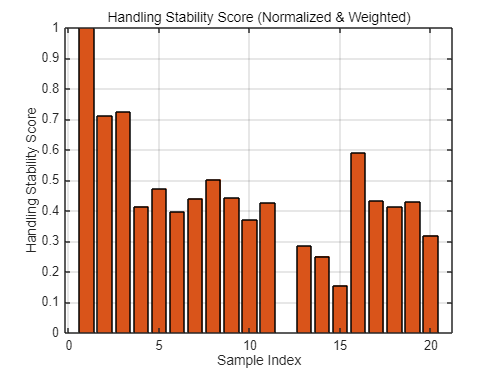

X = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, params_tbl.Comp_R];  % (20 x 4)

% Step 2: 출력 변수 (Vib_Data.mat에서 T_all 불러오기)
load('Vib_Data.mat');  % T_all 포함

% Rename for clarity
roll_angle_rms = T_all.RollAngle_RMS_deg;
lat_acc_rms     = T_all.RMS_LateralAcc_ms2;
heave_rms       = T_all.RMS_HeaveAcc_ms2;
pitch_acc_rms   = T_all.Pitch_Acc_RMS_degps2;
roll_acc_rms    = T_all.Roll_Acc_RMS_degps2;
psd_rms         = T_all.Heave_PSD_RMS_mps2;

% Step 3: 정규화 (값이 작을수록 좋음 → 1 - normalize)
normalize = @(x) (x - min(x)) / (max(x) - min(x));

roll_norm   = normalize(roll_angle_rms);
lat_norm    = normalize(lat_acc_rms);
pitch_norm  = normalize(pitch_acc_rms);
rolla_norm  = normalize(roll_acc_rms);
heave_norm  = normalize(heave_rms);
psd_norm    = normalize(psd_rms);

% Step 4: 점수 계산 (작을수록 점수 높음)
Handling_Score = 0.5 * (1 - roll_norm) + ...
                 0.5 * (1 - lat_norm);

Comfort_Score = 0.3 * (1 - heave_norm) + ...
                0.3 * (1 - psd_norm)   + ...
                0.2 * (1 - pitch_norm) + ...
                0.2 * (1 - rolla_norm);

% Step 5: GPR 모델 학습
gprModel_handling = fitrgp(X, Handling_Score, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

gprModel_comfort = fitrgp(X, Comfort_Score, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

% Step 6: Score 시각화 (색상 지정 포함)
figure;
bar(Handling_Score, 'FaceColor', [0.85 0.33 0.10]);  % 붉은색 (Red-orange)
grid on;
title('Handling Stability Score (Normalized & Weighted)');
xlabel('Sample Index');
ylabel('Handling Stability Score');

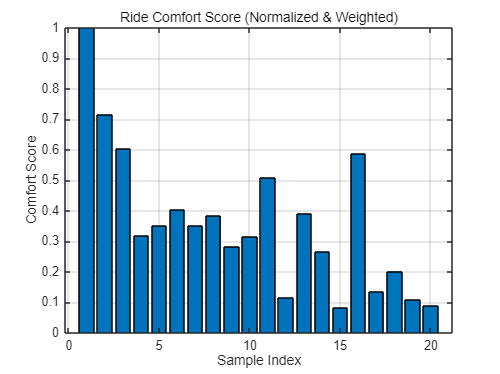


figure;
bar(Comfort_Score, 'FaceColor', [0.00 0.45 0.74]);  % 파란색 (Blue)
grid on;
title('Ride Comfort Score (Normalized & Weighted)');
xlabel('Sample Index');
ylabel('Comfort Score');

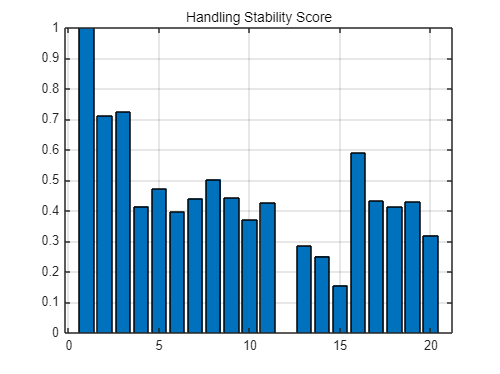

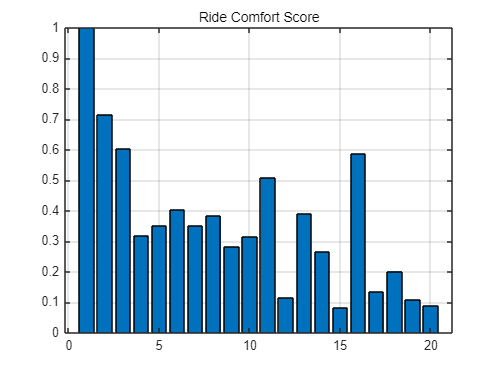

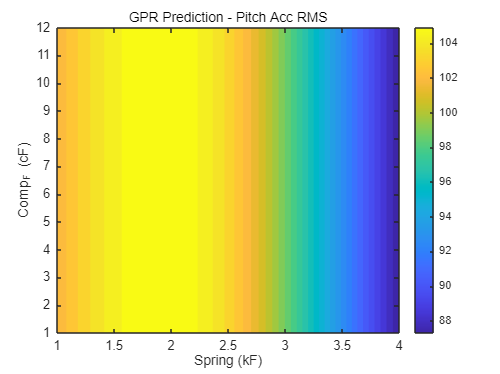

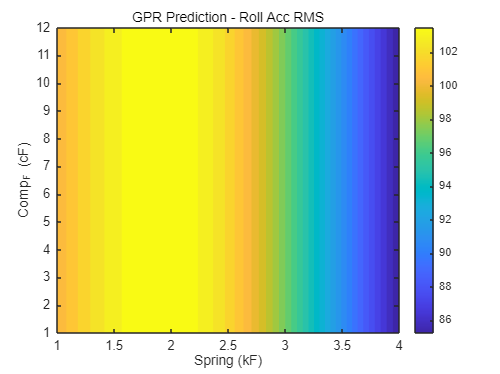

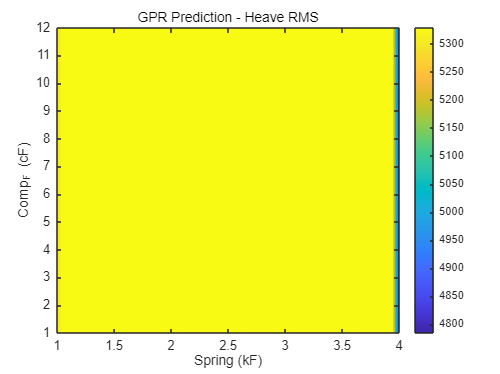

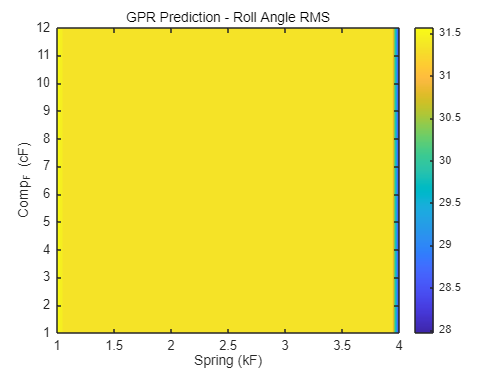

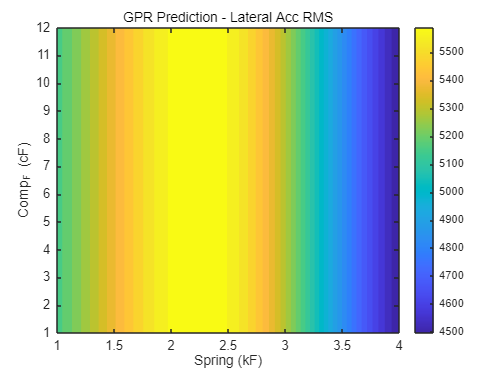

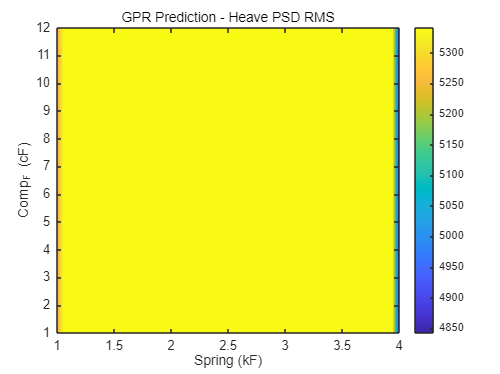


%% Section 8: 각 지표별 GPR 대리모델 시각화 (kF vs cF 기준)

% 입력 변수
X = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, params_tbl.Comp_R];

% 출력 벡터 구성
y_targets = {
    pitch_acc_rms, 'Pitch Acc RMS';
    roll_acc_rms,  'Roll Acc RMS';
    heave_rms,     'Heave RMS';
    roll_angle_rms,'Roll Angle RMS';
    lat_acc_rms,   'Lateral Acc RMS';
    psd_rms,       'Heave PSD RMS'
};

% 고정값: Reb_F, Comp_R 평균
RebF_mean = mean(X(:,3));
CompR_mean = mean(X(:,4));

% kF vs cF grid
kF_grid = linspace(min(X(:,1)), max(X(:,1)), 50);
cF_grid = linspace(min(X(:,2)), max(X(:,2)), 50);
[KF, CF] = meshgrid(kF_grid, cF_grid);
RebF = RebF_mean * ones(size(KF));
CompR = CompR_mean * ones(size(CF));
X_query = [KF(:), CF(:), RebF(:), CompR(:)];

% 시각화 루프
for i = 1:size(y_targets,1)
    y = y_targets{i,1};
    label = y_targets{i,2};

    gprM = fitrgp(X, y, ...
        'KernelFunction', 'ardsquaredexponential', ...
        'Standardize', true);
    
    y_pred = predict(gprM, X_query);
    y_grid = reshape(y_pred, size(KF));

    figure;
    contourf(KF, CF, y_grid, 30, 'LineColor','none');
    colorbar;
    xlabel('Spring (kF)');
    ylabel('Comp_F (cF)');
    title(['GPR Prediction - ' label]);
end

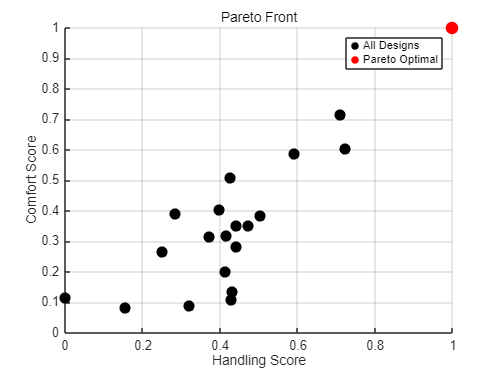



%% Section 9: Pareto 최적화 및 사용자 기반 추천 설계

% Step 1: Score Matrix
score_handling = Handling_Score(:);
score_comfort = Comfort_Score(:);
score_matrix = [-score_handling, -score_comfort];  % Pareto는 최소화 문제로 처리

% Step 2: Pareto Front
pareto_flags = paretofront(score_matrix);

% Step 3: 시각화
figure;
scatter(score_handling, score_comfort, 80, 'k', 'filled'); hold on;
scatter(score_handling(pareto_flags), score_comfort(pareto_flags), ...
        100, 'r', 'filled');
xlabel('Handling Score');
ylabel('Comfort Score');
title('Pareto Front');
legend('All Designs', 'Pareto Optimal');
grid on;


% Step 4: 사용자 가중치 기반 점수
w_h = 0.1;
w_c = 0.9;
total_score = w_h * score_handling + w_c * score_comfort;

% Step 5: Pareto 내 최고점 탐색
pareto_idx = find(pareto_flags);
[~, local_best] = max(total_score(pareto_idx));
best_idx = pareto_idx(local_best);

% Step 6: 결과 출력
fprintf('\n== 최적 설계 (Pareto 내 사용자 가중치 기반) ==\n');


== 최적 설계 (Pareto 내 사용자 가중치 기반) ==


fprintf('Design #%d\n', best_idx);

Design #1


fprintf('Handling Score = %.4f\n', score_handling(best_idx));

Handling Score = 1.0000


fprintf('Comfort Score  = %.4f\n', score_comfort(best_idx));

Comfort Score  = 1.0000


fprintf('Total Score    = %.4f\n', total_score(best_idx));

Total Score    = 1.0000


disp('파라미터 값:');

파라미터 값:


disp(params_tbl(best_idx,:));

    x_    Spring    Comp_F    Reb_F    Comp_R    Reb_R
    __    ______    ______    _____    ______    _____

    1       4         7         6        6        10  




%%%%%%%%%%%%%%%%%%%%%%
%% Section 10: GPR 기반 연속 설계 공간 최적 설계 탐색 (5개 변수 + 제약 조건 포함)

n_samples = 100000;
n_vars = 5;

lhs = lhsdesign(n_samples, n_vars, ...
    'criterion', 'maximin', ...
    'iterations', 100);  % 다양한 시도 중 간격이 가장 좋은 조합 선택

% 변수별 범위 스케일링
spring_samples = lhs(:,1) * (4 - 1) + 1;
compF_samples  = lhs(:,2) * (12 - 1) + 1;
rebF_samples   = lhs(:,3) * (22 - 1) + 1;
compR_samples  = lhs(:,4) * (12 - 1) + 1;
rebR_samples   = lhs(:,5) * (22 - 1) + 1;

X_query_full = [spring_samples, compF_samples, rebF_samples, compR_samples, rebR_samples];



% Step 2: GPR 모델 재학습 (X와 점수가 기존 4개 기준이었다면, 새 데이터에 맞춰 새 학습 필요)
% → 여기서는 4D GPR 모델 그대로 쓴다면 X_query_full의 5번째 변수는 무시됩니다.
% → **해결 방법:** 기존 Reb_F 자리에 rebR_samples를 넣거나,
%     → 전체 5개 파라미터로 GPR을 새로 학습해야 함.

% 예시) 5차원 GPR 모델 학습
X_train = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, params_tbl.Comp_R, params_tbl.Reb_R];  % ← Reb_R 포함
gprModel_handling = fitrgp(X_train, Handling_Score, 'KernelFunction','ardsquaredexponential','Standardize',true);
gprModel_comfort  = fitrgp(X_train, Comfort_Score,  'KernelFunction','ardsquaredexponential','Standardize',true);

% Step 3: 예측
H_pred = predict(gprModel_handling, X_query_full);
C_pred = predict(gprModel_comfort, X_query_full);

% Step 4: Total Score
w_h = 0.2;
w_c = 0.8;
total_score = w_h * H_pred + w_c * C_pred;

% Step 5: 최적 설계 탐색
[~, best_idx] = max(total_score);
best_design = X_query_full(best_idx, :);

% Step 6: 출력
fprintf('\n== GPR 기반 최적 설계 (5변수, Level 기준) ==\n');


== GPR 기반 최적 설계 (5변수, Level 기준) ==


fprintf('>> 가중치 비율 (Handling : Comfort) = %.1f : %.1f\n', w_h, w_c);

>> 가중치 비율 (Handling : Comfort) = 0.2 : 0.8


fprintf('Spring Level     = %.2f\n', best_design(1));

Spring Level     = 3.98


fprintf('Comp_F Level     = %.2f\n', best_design(2));

Comp_F Level     = 7.40


fprintf('Reb_F Level      = %.2f\n', best_design(3));

Reb_F Level      = 5.94


fprintf('Comp_R Level     = %.2f\n', best_design(4));

Comp_R Level     = 7.10


fprintf('Reb_R Level      = %.2f\n', best_design(5));

Reb_R Level      = 10.61


fprintf('Handling Score   = %.4f\n', H_pred(best_idx));

Handling Score   = 0.9888


fprintf('Comfort Score    = %.4f\n', C_pred(best_idx));

Comfort Score    = 0.9691


fprintf('Total Score      = %.4f\n', total_score(best_idx));

Total Score      = 0.9731


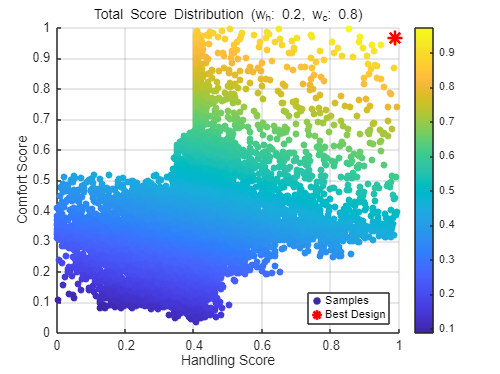


% Step 7: 2D Plot of Score Distribution with Optimal Point
figure;
scatter(H_pred, C_pred, 30, total_score, 'filled'); hold on;
plot(H_pred(best_idx), C_pred(best_idx), 'r*', 'MarkerSize', 12, 'LineWidth', 2);
xlabel('Handling Score');
ylabel('Comfort Score');
title(sprintf('Total Score Distribution (w_h: %.1f, w_c: %.1f)', w_h, w_c));
colorbar;
legend('Samples', 'Best Design', 'Location', 'southeast');
xlim([0 1]);  % X축 범위 설정
ylim([0 1]);  % Y축 범위 설정
grid on;

% 가중치 반복 결과 저장용 변수 초기화
results = [];

% 반복 수행: w_h from 0.1 to 0.9, step 0.1
for w_h = 0.1:0.1:0.9
    w_c = 1 - w_h;

    % Total Score 계산
    total_score = w_h * H_pred + w_c * C_pred;

    % 최적 설계 인덱스
    [~, best_idx] = max(total_score);
    best_design = X_query_full(best_idx, :);

    % 결과 저장
    results = [results; ...
        w_h, w_c, ...
        best_design(1), best_design(2), best_design(3), best_design(4), best_design(5), ...
        H_pred(best_idx), C_pred(best_idx), total_score(best_idx)];
end

% 결과 테이블로 변환
results_tbl = array2table(results, ...
    'VariableNames', {'w_h', 'w_c', ...
                      'Spring_Level', 'Comp_F_Level', 'Reb_F_Level', 'Comp_R_Level', 'Reb_R_Level', ...
                      'Handling_Score', 'Comfort_Score', 'Total_Score'});

% 결과 출력
disp('== Summary Table of Optimal Designs for Different Weights ==');

== Summary Table of Optimal Designs for Different Weights ==


disp(results_tbl);

    w_h    w_c    Spring_Level    Comp_F_Level    Reb_F_Level    Comp_R_Level    Reb_R_Level    Handling_Score    Comfort_Score    Total_Score
    ___    ___    ____________    ____________    ___________    ____________    ___________    ______________    _____________    ___________

    0.1    0.9       3.9953          11.605         6.4161          9.7256         9.9115          0.85453           0.99686         0.98263  
    0.2    0.8       3.9844          7.4037         5.9383          7.0954         10.607          0.98884           0.96911         0.97306  
    0.3    0.7       3.9844          7.4037         5.9383          7.0954         10.607          0.98884           0.96911         0.97503  
    0.4    0.6       3.9844          7.4037         5.9383          7.0954         10.607          0.98884           0.96911           0.977  
    0.5    0.5       3.9844          7.4037         5.9383          7.0954         10.607          0.98884           0.96911         0.97898 


% 필요 시 테이블 저장
% writetable(results_tbl, 'OptimalDesigns_by_Weight.csv');
